# **MSE490 Project **

## **Part 1: Creating Discrete Time Model**

clc 
clear all 

% System Model 
Fk = [0 0 0 0 0 0.125 0.125 0.125 0.125 0.125 0.125 0.125 0.125 0.125 0.0025 0.0025 0.0025  0.0025 0.0025 0.0025;
     1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0;
     0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0;
     0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0;
     0 0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0;
     0 0 0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0;
     0 0 0 0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0;
     0 0 0 0 0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0;
     0 0 0 0 0 0 0 1 0 0 0 0 0 0 0 0 0 0 0 0;
     0 0 0 0 0 0 0 0 1 0 0 0 0 0 0 0 0 0 0 0;
     0 0 0 0 0 0 0 0 0 1 0 0 0 0 0 0 0 0 0 0;
     0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 0 0 0 0 0;
     0 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 0 0 0 0;
     0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 0 0 0;
     0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 0 0;
     0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 0;
     0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0;
     0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0;
     0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0;
     0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 0;];
 
Gk = zeros(20,1);
Hk = [0 0 0 0 0 0 0 0 0 0 0 0 0 0.5 0.5 0 0 0 0 0;];
Ik = 0;

% Discrete Time model for Equations 1-4
sys = ss(Fk,Gk,Hk,Ik,-1);

## **Part 2: Simulating Kalman Filter for 100 days**

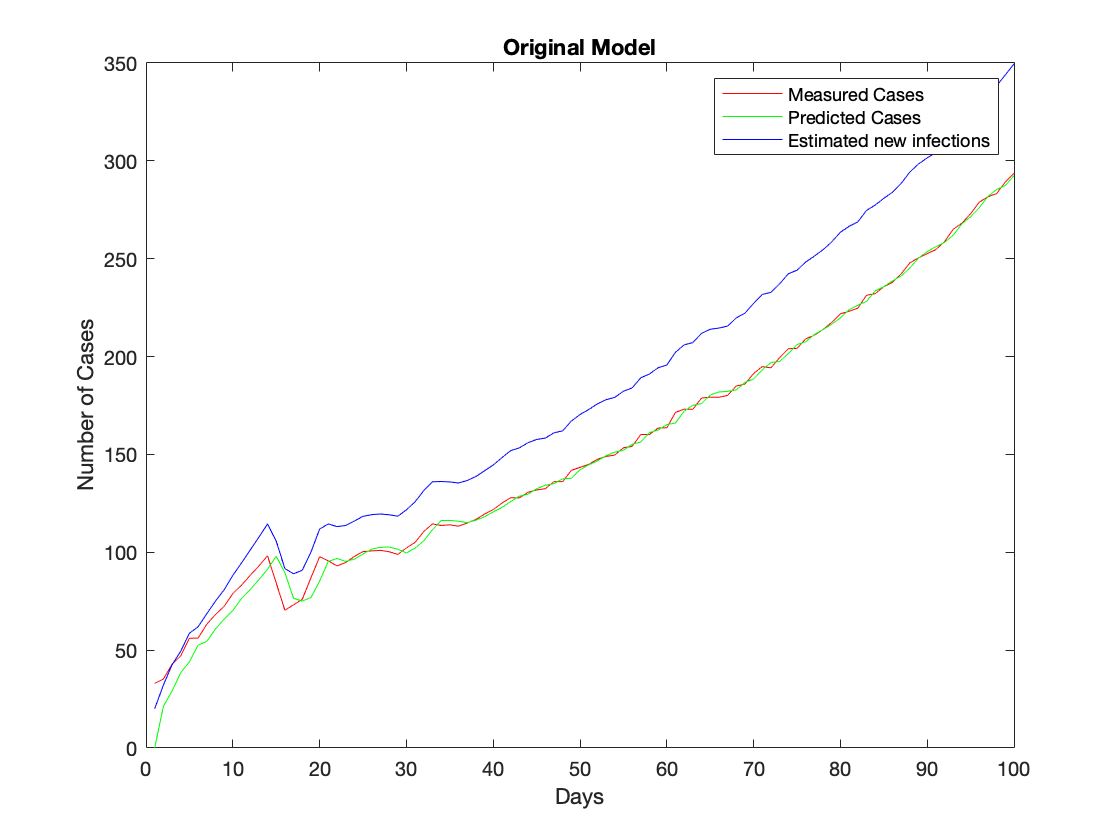

% Initial Estimate
X_initial (1:20,1) = 0; 

% Initial error in the estimation
P_initial = eye(20,20);

% Kalman Filter Iteration Process - 
%   kalmanFilter(Fk,Hk,X_initial,P_initial,Q,R)
%   Fk & Hk = System Model
%   X_Initial = initial estimate
%   P_Initial = initial error in the estimation of the true state
%   Qk = Process Noise
%   Rk = Uncertainty in the measurement
%   For Part 2: Given Qk = 2 and Rk = 1

[days,Yk,Predicted_Yk,Updated_new_infections]=kalmanFilter(Fk,Hk,X_initial, P_initial,2,1);

plot(days,Yk,'r',days,Predicted_Yk,'g',days,Updated_new_infections,'b');
title('Original Model');
xlabel('Days');
ylabel('Number of Cases');
legend('Measured Cases','Predicted Cases', 'Estimated new infections');

## Part 3 - Kalman Filter using BC CDC Data

**a)**

Since, part 3 of the project is an open ended question and given the limited time and resources it was difficult to study and research the dynamics of covid spread and come up with our own model to estimate spread of covid. Therefore, instead of coming up with a new model to estimate the covid spread based on the BC CDC data given, I decided to makes adjustments to the given model and see how well the given model could estimate the true number of cases per day by using the given CDC data points. 

Initially, I used the CDC data points as my measured inputs to my original model given in Question 1. I had suspected the model to not work for the real world data. Following is the Kalman filter used to estimate the true number of cases per day using the BC CDC data points as inputs with Qk = 2 and Rk = 1. (i.e. Process noise covariance = 2 and Measurement Noise = 1) .

**Simulating Kalman Filter for BC CDC Data using the Qk=2 and Rk=1 as given initially.**

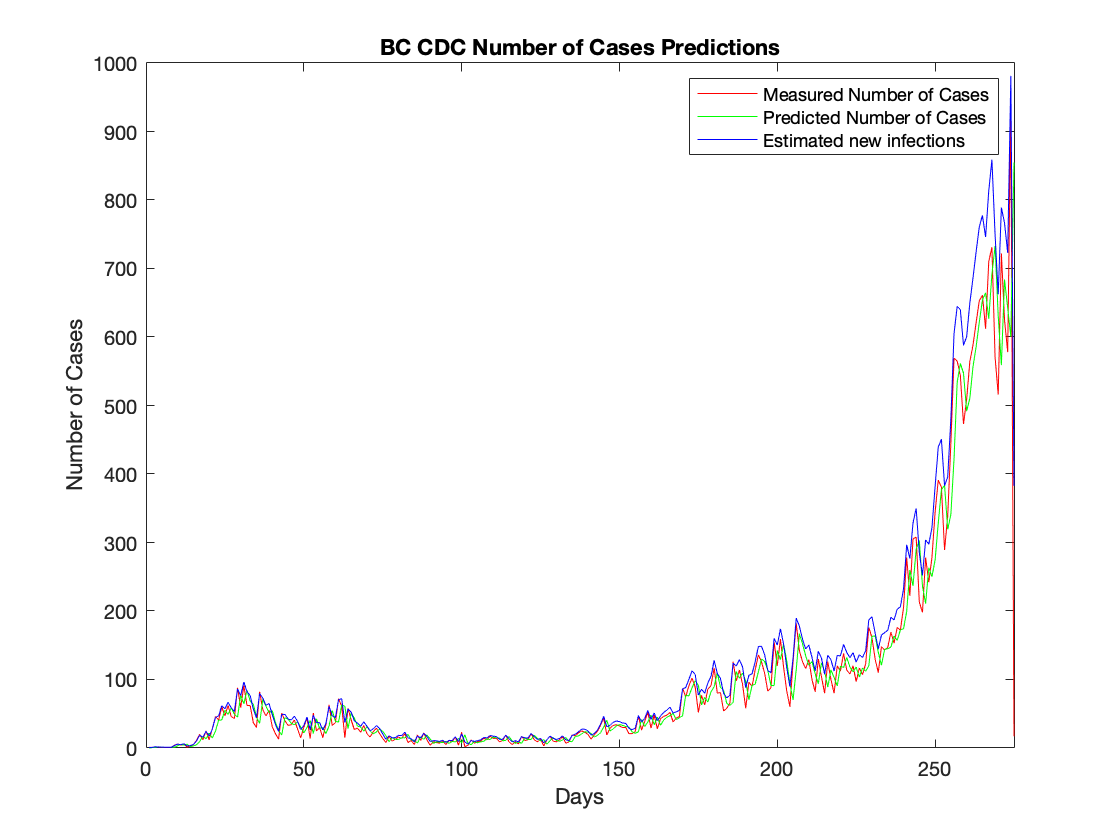

% Initial Estimate
X_initial (1:20,1) = 0; 

% Initial error in the estimation
P_initial = eye(20,20);

% Kalman Filter Iteration Process - 
%   kalmanFilter(Fk,Hk,X_initial,P_initial,Q,R)
%   Fk & Hk = System Model
%   X_Initial = initial estimate
%   P_Initial = initial error in the estimation of the true state
%   Qk = Process Noise
%   Rk = Uncertainty in the measurement
%   For Part 2: Given Qk = 2 and Rk = 1

[days,Yk,Predicted_Yk,Updated_new_infections]=kalmanFilter2(Fk,Hk,X_initial, P_initial,2,1);

plot(days,Yk,'r',days,Predicted_Yk,'g',days,Updated_new_infections,'b');
title('BC CDC Number of Cases Predictions');
xlim([0 275]);
xlabel('Days');
ylabel('Number of Cases');
legend('Measured Number of Cases','Predicted Number of Cases', 'Estimated new infections');

From the plot above, surprisingly the given model is able to coverge to the BC CDC data using the given model. 

Out of Curiousity, I adjusted the process noise covariance and measurement uncertainty to see if the Kalman filter estimated output will coverge more toward the measured output of the BC CDC data. The changes made to Qk and Rk, also the resulting plots are in the following sections. 

### **Simulating Kalman Filter for BC CDC Data - Adjusting Process Noise Covariance(Qk) and Measurement Uncertainty (Rk)**

- Assuming that the BC CDC data has more uncertainty than the process of estimating the true state of the system (i.e. the number infections),  I reduced the process noise covariance to 1 and increased the uncertainty in the measurement to 5. By doing so, Kalman filter will give less weight to the measurement of the number of cases (from BC CDC data) and will give more weight to the previous estimated number of cases because we assumed that BC CDC data has more uncertainty. 

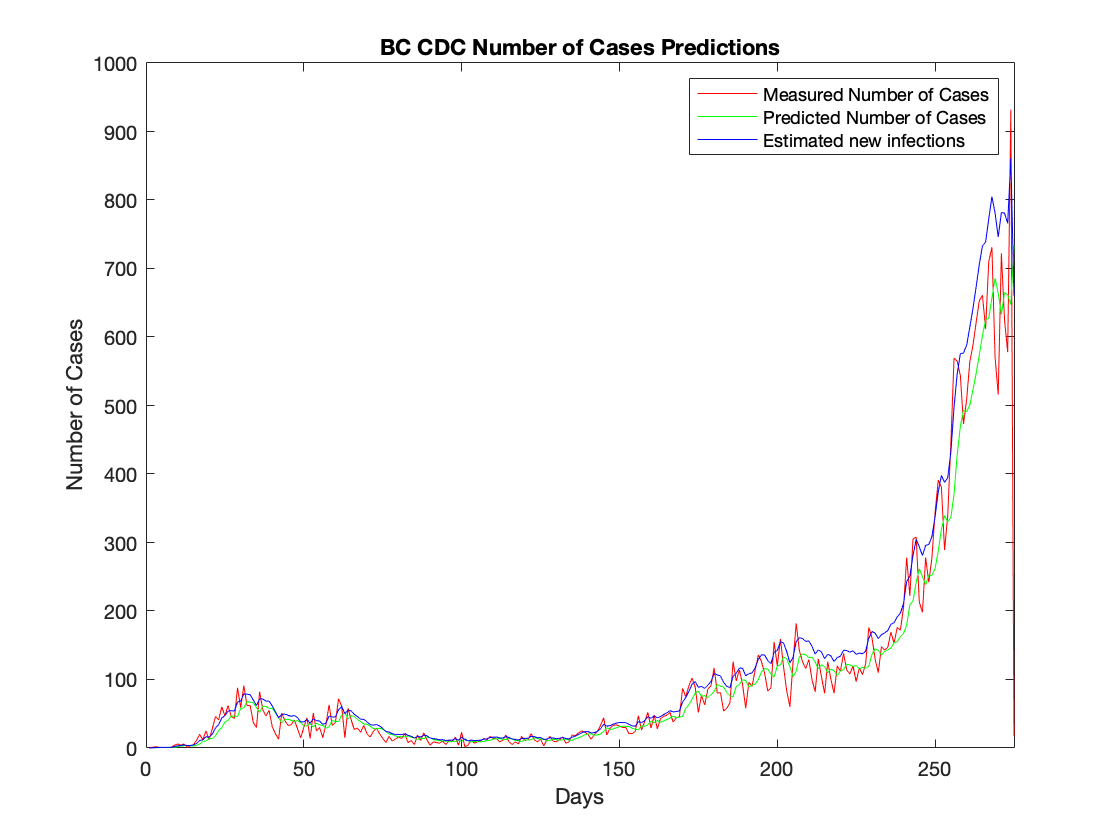

% Initial Estimate
X_initial (1:20,1) = 0; 

% Initial error in the estimation
P_initial = eye(20,20);

% Kalman Filter Iteration Process - 
%   kalmanFilter(Fk,Hk,X_initial,P_initial,Q,R)
%   Fk & Hk = System Model
%   X_Initial = initial estimate
%   P_Initial = initial error in the estimation of the true state
%   Qk = Process Noise
%   Rk = Uncertainty in the measurement
%   Qk =1  Rk =5;

[days,Yk,Predicted_Yk,Updated_new_infections]=kalmanFilter2(Fk,Hk,X_initial, P_initial,1,10);

plot(days,Yk,'r',days,Predicted_Yk,'g',days,Updated_new_infections,'b');
title('BC CDC Number of Cases Predictions');
xlim([0 275]);
xlabel('Days');
ylabel('Number of Cases');
legend('Measured Number of Cases','Predicted Number of Cases', 'Estimated new infections');

From the plot above, we can notice that our kalman filter estimation of the true number of cases is almost converging to the true value, but not quite there yet. So, in the next section I decided to adjust Qk and Rk such that, we assume the BC CDC data is more accurate and that our estimations are more unstable.

- Assuming that the BC CDC data is more accurate and the estimations of the true state are more unstable, I increased the process noise covariance to 4 and set the uncertainty in the measurement to 1. By doing so, Kalman filter will give more weight to the measurement of the number of cases and will give less weight to the previous estimated number of cases because we assumed that BC CDC data is more accurate. 

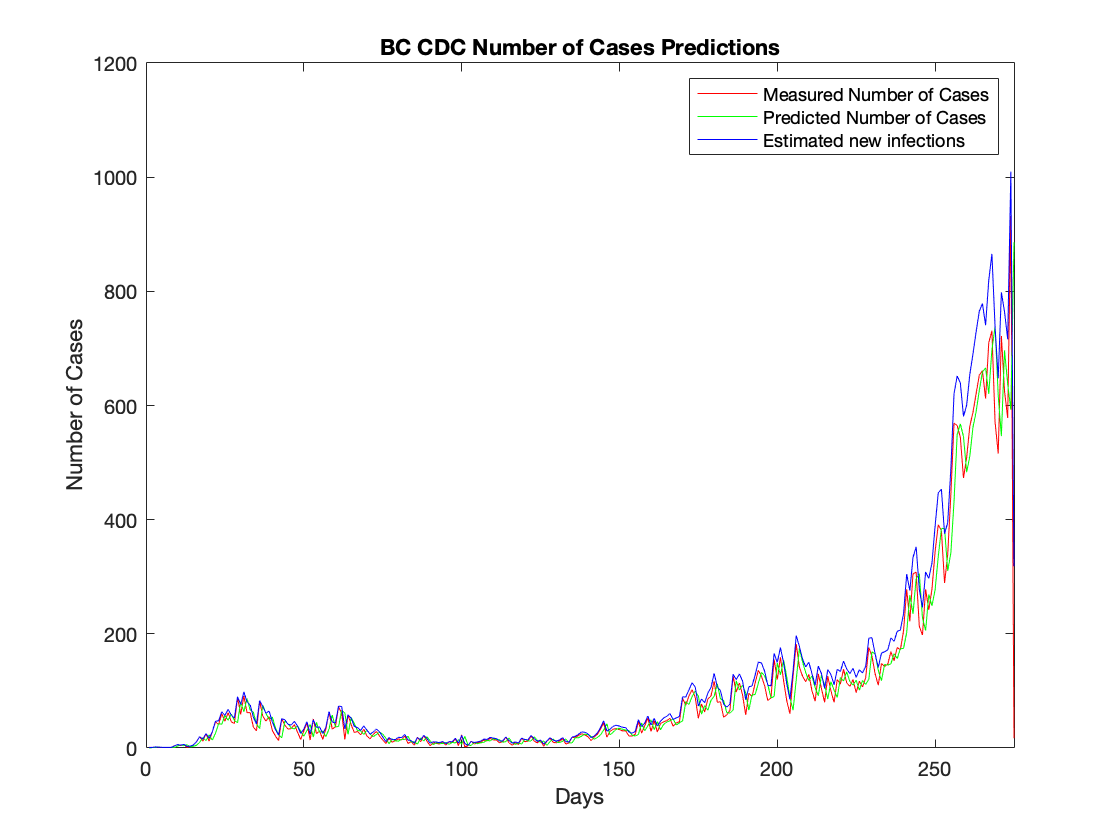

% Initial Estimate
X_initial (1:20,1) = 0; 

% Initial error in the estimation
P_initial = eye(20,20);

% Kalman Filter Iteration Process - 
%   kalmanFilter(Fk,Hk,X_initial,P_initial,Q,R)
%   Fk & Hk = System Model
%   X_Initial = initial estimate
%   P_Initial = initial error in the estimation of the true state
%   Qk = Process Noise
%   Rk = Uncertainty in the measurement
%   Qk =4;  Rk =1;
[days,Yk,Predicted_Yk,Updated_new_infections]=kalmanFilter2(Fk,Hk,X_initial, P_initial,4,1);

plot(days,Yk,'r',days,Predicted_Yk,'g',days,Updated_new_infections,'b');
title('BC CDC Number of Cases Predictions');
xlim([0 275]);
xlabel('Days');
ylabel('Number of Cases');
legend('Measured Number of Cases','Predicted Number of Cases', 'Estimated new infections');

The plot above shows that assuming that BC CDC is more accurate than our process of estimating the true state gives a better estimation of the true number of cases per days, I.e. Kalman filter converges more towards the true value. I make this conclusion based on the fact that the plot shows that the "Predicted Number of Cases" is almost on top of the "Measured Number of Cases", as seen in the plot above.  

**Question 3 - Part a)**: Based on my experiments above and the fact that the given model for this project is able to estimate the true number of cases (as shown in previous sections), I would set the process noise covariance (Qk) higher than the uncertainty in BC CDC data (Rk). I'm suggesting these merely because I don't much information about how the given model was setup but I do know that the measured number of cases is coming from a reliable source so I set the uncertainty lower. Surprisinng the model given to us in Question 1 was able to converge to the true number of cases with Kalman Filter as shown in the plot above for Qk =4 and Rk=1.  

**b) ** Making 1 day Forecast starting at day 150 - using the model with Qk = 4 and Rk = 1

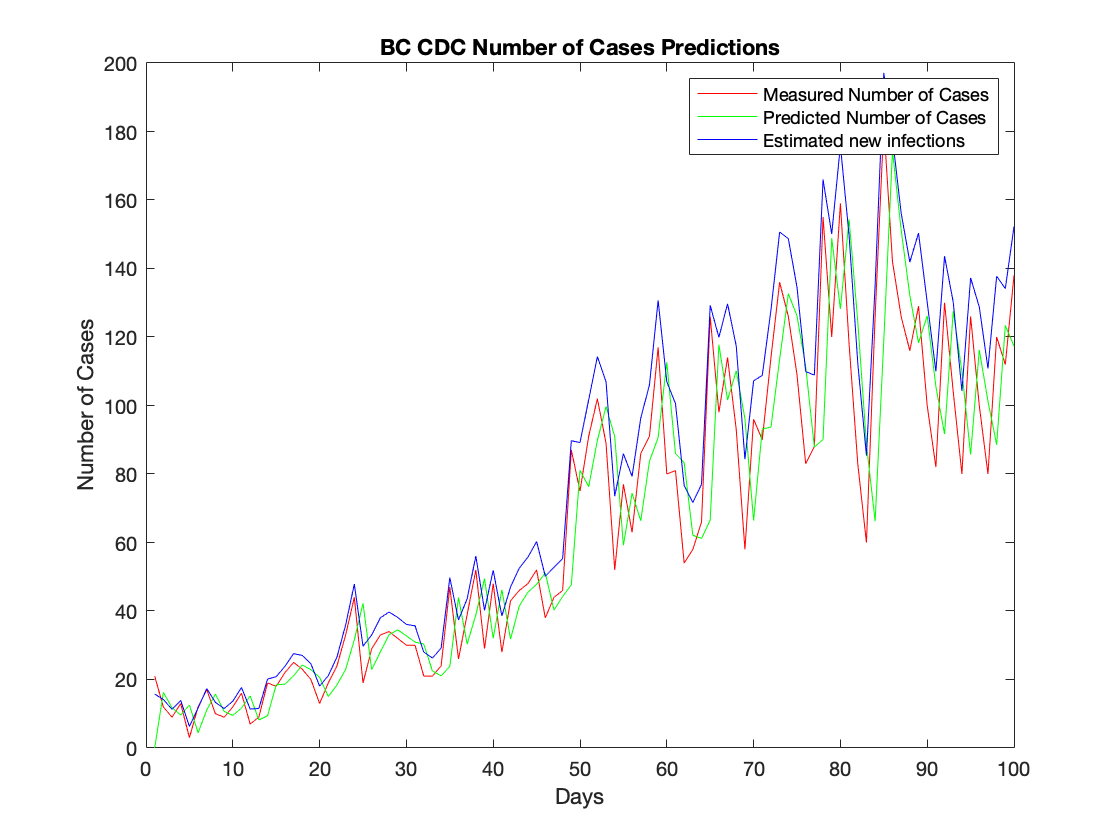

% Initial Estimate
X_initial (1:20,1) = 0; 

% Initial error in the estimation
P_initial = eye(20,20);

% Kalman Filter Iteration Process - 
%   kalmanFilter(Fk,Hk,X_initial,P_initial,Q,R)
%   Fk & Hk = System Model
%   X_Initial = initial estimate
%   P_Initial = initial error in the estimation of the true state
%   Qk = Process Noise
%   Rk = Uncertainty in the measurement
%   Qk =4;  Rk =1;
[days,Yk,Predicted_Yk,Updated_new_infections]=kalmanFilter3(Fk,Hk,X_initial, P_initial,4,1);

plot(days,Yk,'r',days,Predicted_Yk,'g',days,Updated_new_infections,'b');
title('BC CDC Number of Cases Predictions');
xlim([0 100]);
xlabel('Days');
ylabel('Number of Cases');
legend('Measured Number of Cases','Predicted Number of Cases', 'Estimated new infections');

Based on the model above, where Qk = 4 and Rk =1, i.e. I assumed the measurements of cases from BC CDC are more accurate and the process of estimation has more noise, the estimated new infections on day 151 was 16 cases and the true value is 21 cases. 

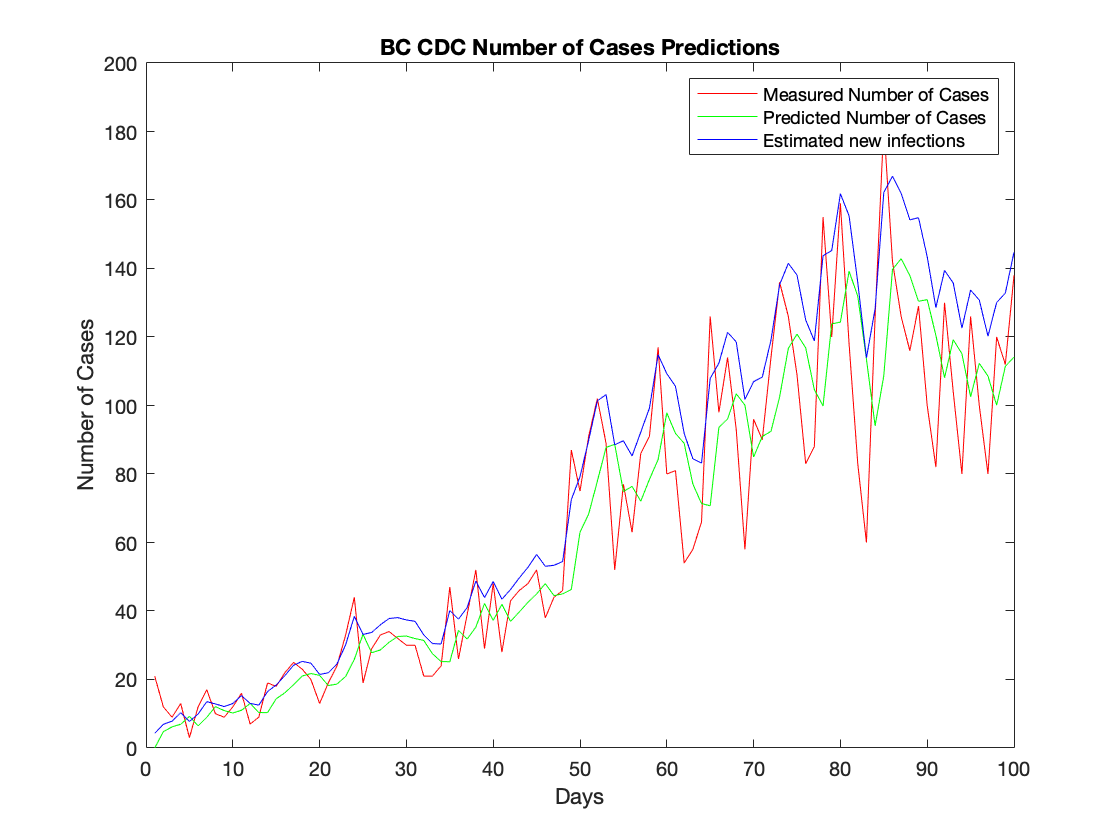

% Initial Estimate
X_initial (1:20,1) = 0; 

% Initial error in the estimation
P_initial = eye(20,20);

% Kalman Filter Iteration Process - 
%   kalmanFilter(Fk,Hk,X_initial,P_initial,Q,R)
%   Fk & Hk = System Model
%   X_Initial = initial estimate
%   P_Initial = initial error in the estimation of the true state
%   Qk = Process Noise
%   Rk = Uncertainty in the measurement
%   Qk =1;  Rk =4;
[days,Yk,Predicted_Yk,Updated_new_infections]=kalmanFilter3(Fk,Hk,X_initial, P_initial,1,4);

plot(days,Yk,'r',days,Predicted_Yk,'g',days,Updated_new_infections,'b');
title('BC CDC Number of Cases Predictions');
xlim([0 100]);
xlabel('Days');
ylabel('Number of Cases');
legend('Measured Number of Cases','Predicted Number of Cases', 'Estimated new infections');

Based on the model above, where Qk = 1 and Rk =4, i.e. I assumed the measurements of cases from BC CDC have more uncertainty and the process of estimation has less noise, the estimated new infections on day 151 was 4 cases and the true value is 21 cases. 

So, based on the two variations Qk and Rk, the one where I assumed the measurements from BC CDC were more accurate in comparison to the process of estimating the true number of cases gave a relatively better estimation of the true cases. 

**c)  **Improving Predictions

The model used for forecasting the spread of covid is not a realistic model as it doesn't account for many biases. Based on my research, the best approach to deriving the dynamic model of a pandemic (to achieve better predictions for the spread of covid) is to integrate an Unscented Kalman Filter with a mean-field Susceptible-Infected-Recovery-Death (SIRD) model proposed by Kermack and McKendrick [1]. 

The SIRD model is governed by a set of differential equations that compute instantaneous values of an event. COVID-19 cases being a discrete-time event lack the instantaneous effect in the differential equation based SIRD model [2]. This is where the Unscented Kalman filter comes in to play, which is a non-linear estimation algorithm that is used to accurately and timely forecast the dynamic state in a nonlinear system [3]. Therefore, the spread of COVID-19 (i.e. the number of cases everyday) can be best predicted by combining a non-linear kalman filter with a SIRD model, where SIRD model estimates the number of COVID-19 active cases, recovered cases and death cases using a set of differential equations. 

## References

[1] Kermack WO, McKendrick AG. A contribution to the mathematical theory of epidemics. Proceedings of the royal society of london Series A, *Containing papers of a mathematical and physical character*. 1927;115(772):700–721. 

[2]"The SIR Model for Spread of Disease - The Differential Equation Model | Mathematical Association of America", *Maa.org*, 2020. [Online]. Available: https://www.maa.org/press/periodicals/loci/joma/the-sir-model-for-spread-of-disease-the-differential-equation-model. [Accessed: 06- Dec- 2020].

[3] E. A. Wan and R. van der Merwe, *The Unscented Kalman Filter for Nonlinear Estimation*. IEEE, 2000, pp. 153-158.